## TCLab Step Test Simulation

Goal: Compare Step response data to simulated data from TCLab

viewSolution(false)

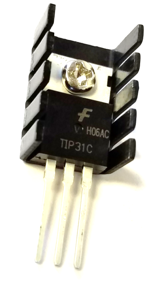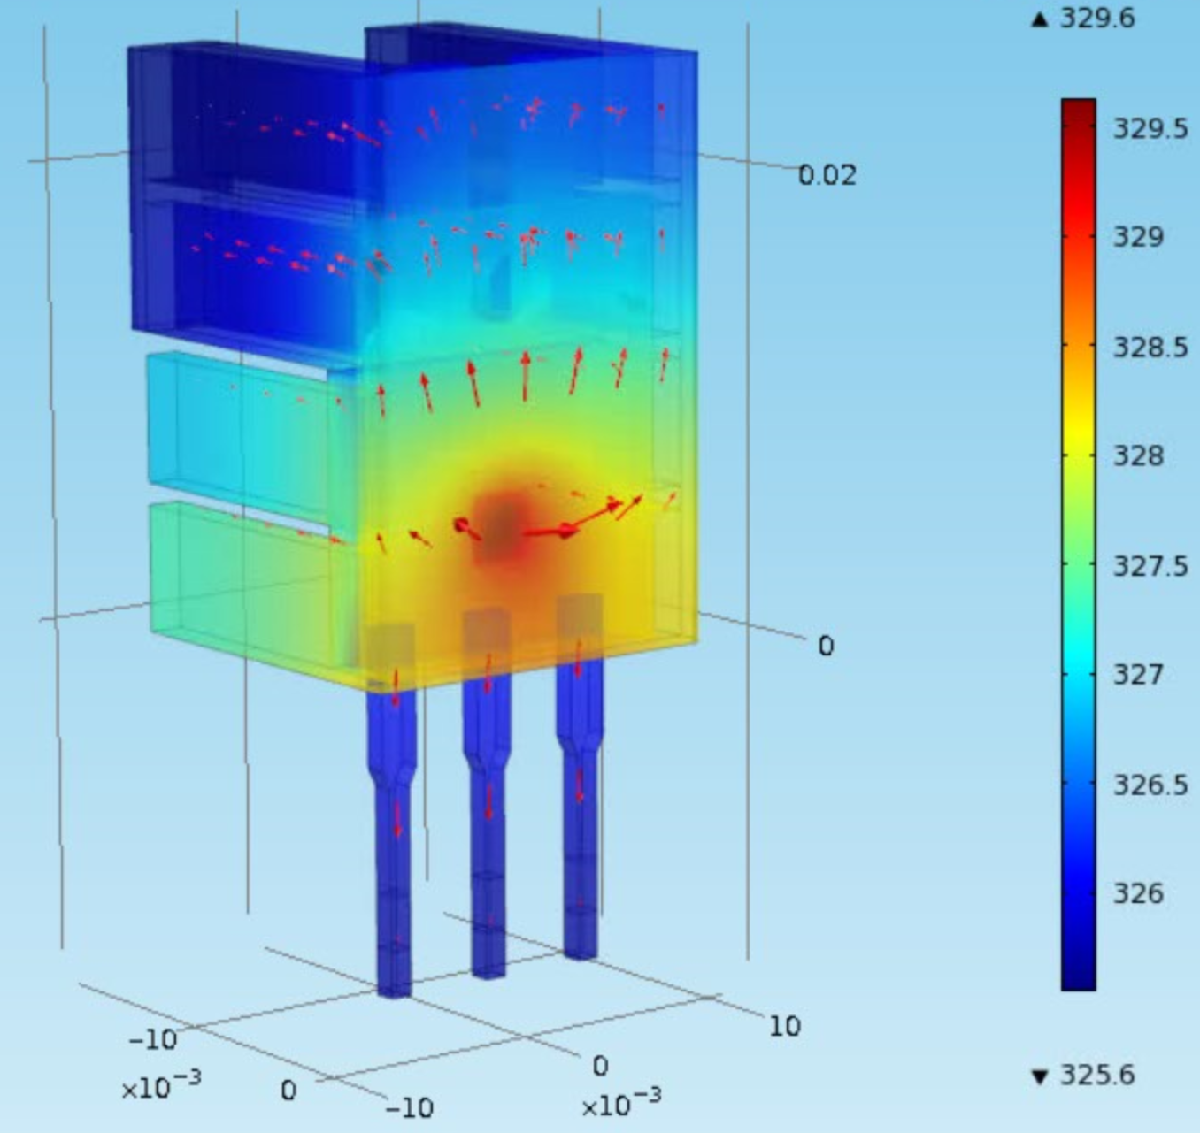

Simplified dymanic model of TCLab:


$$\tau_p\frac{dT}{dt}=(T_a-T) +K_pQ$$


With the temperature initially at ambient temperature ($Ta$), simulate the change in temperature over the 5 minutes when heater $Q$ is adjusted to $50\%$. Use a values of $\tau = 120$ sec, $K_p = 0.8 \frac{^\circ C}{\%}$, and $T_a =23^\circ C$. Compare the simulated temperature response to data from the TCLab. Add a simulation prediction to the script below to compare with the TCLab data.

### TCLab Step Response

% clear code
clc;clear all;close all;

try
    % initialize storage array
    T1 = zeros(301, 1);
    tm = zeros(301, 1);
    
    % connect to TCLab
    lab = tclab;
    lab.Q1(50);
    tic;
    for i=1:length(tm)
        T1(i) = lab.T1;
        tm(i) = toc;
        pause(1);
        plot(tm(1:i), T1(1:i), 'r.')
        
        
    end
    lab.off;
    clear lab;

catch
    lab.off;
    clear lab;
end    

### Simulation

Simulate the change in temperature as the heater is set to 50% for 5 minutes

Using a linspace for the time range from 0 to 300 seconds, use ode45 to simulate the Temperature of the TCLab while the heater is at 50% using the simplified energy balance provided above

USING `linspace` FOR THE TIME RANGE FROM O TO 360 SECONDS, USE` ode45 `TO SIMULATE THE TEMPERATURE OF THE TCLab WHILE THE HEATER IS AT 50% USING THE SIMPLIFIED ENERGY BALANCE PROVIDED ABOVE

ADD PLOT OF SIMULATION AND STEP_TEST BELOW

ADD FUNCTION TO INTEGRATE USING` ode45 ``BELOW`

### Solution

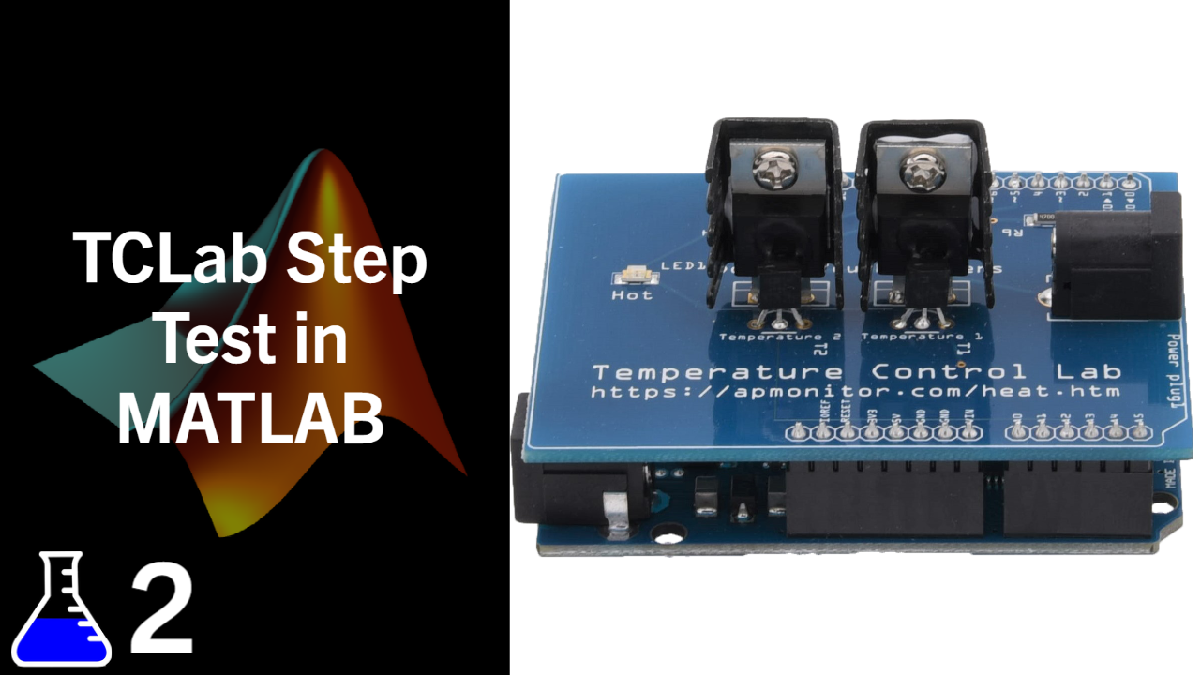

[View Solution Video](https://youtu.be/Q7ACUJZgz3c)

function viewSolution(view)
if view
disp("time = linspace(0, 350, 351);" + newline + ...
     "% Simulate" + newline + ...
     "[t, T] = ode45(@(t, T) sim_TCLAb(t, T, 50), time, 23)" + newline + ...
     "" + newline + ...
     "% ADD PLOT OF SIMULATION AND STEP_TEST BELOW" + newline + ...
     "plot(tm, T1, 'r.')" + newline + ...
     "hold on;" + newline + ...
     "plot(t, T, 'b-')" + newline + ...
     "xlabel('Time (sec)')" + newline + ...
     "ylabel('Temperature (deg C)')" + newline + ...
     "legend({'Data', 'Simulation'})" + newline + ...
     "hold off" + newline + ...
     "" + newline + ...
     "% ADD FUNCTION TO INTEGRATE BELOW" + newline + ...
     "function dTdt = sim_TCLAb(~, T, u)" + newline + ...
     "taup = 120; % time constant (sec)" + newline + ...
     "Ta = 23;    % ambient temperature" + newline + ...
     "Kp = .8;     % gain (deg C/%)" + newline + ...
     "dTdt = ((Ta-T) + Kp * u)/taup;" + newline + ...
	 "end")
end
end
